# Analysis of Cooling within a semi-infinite glass cylinder (practice)

## Material Parameters:

% Density
rho = 2500

rho = 2500

% Heat capacity
c = 750

c = 750

% Conductivity
k = 1.4

k = 1.4000

## Size Paramters:

dia = 20/1000 %mm

dia = 0.0200

nodes = 10

nodes = 10


delta_x = (dia/2) / nodes

delta_x = 1.0000e-03

## Modelling parameters:

h = 1000

h = 1000


T_start = 900

T_start = 900

T_inf = 20

T_inf = 20

t_max = 60

t_max = 60

t_steps = 10000

t_steps = 10000


delta_t = t_max/t_steps

delta_t = 0.0060

## Computation

data = [T_start * ones(1,nodes); zeros(t_steps-1, nodes)]

data =    900   900   900   900   900   900   900   900   900   900
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



for i = 2:t_steps
    new_row = zeros(1,nodes);
    new_row(1) = centreHT(data(i-1, 1),data(i-1,2),rho, c, k, delta_x, delta_t);
    for node = 2:(length(new_row) - 1)
        new_row(node) = internalHT(data(i-1, node), data(i-1, node-1), data(i-1, node+1), rho, c, k, delta_x, delta_t);
    end
    test = surfaceHT(data(i-1, end), data(i-1, end-1), T_inf, rho, c, k, h, delta_x, delta_t);
    new_row(end) = surfaceHT(data(i-1, end), data(i-1, end-1), T_inf, rho, c, k, h, delta_x, delta_t);

    data(i,:) = new_row;
end

data(end,:)

ans =   414.4348  409.9248  396.4973  374.4581  344.3095  306.7389  262.6040  212.9133  158.8036  101.5135


## Plot

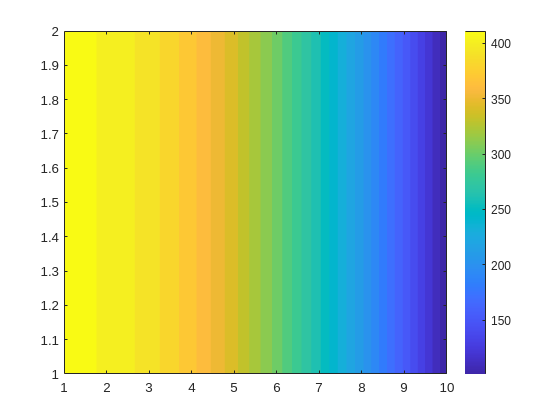

contourf([data(end,:); data(end,:)], 1:10:1000, "LineColor", "none")
colorbar